%% ============================================================
% CNN-BiLSTM Multi-Model Ensemble using selected CMIP6-GCMs
% Entire historical period (1970-2014)
% Sample grid: Longitude = 82.625, Latitude = 21.875
%% ============================================================
clc; clear; close all;

excelFile = 'GCM data.xlsx';

% Training-testing split
trainRatio = 0.75;

% CNN-BiLSTM hyperparameters
numHiddenUnits   = 12;
dropoutRate      = 0.10;
maxEpochs        = 150;
miniBatchSize    = 128;
initialLearnRate = 0.001;

rng(42);

%% ================= LOAD EXCEL DATA ===========================

T = readtable(excelFile, 'VariableNamingRule', 'preserve');

disp('Excel columns detected:');

Excel columns detected:


disp(T.Properties.VariableNames');

    {'Date'         }
    {'IMD'          }
    {'ACCESS-CM2'   }
    {'ACCESS-ESM1-5'}
    {'BCC-CSM2-MR'  }
    {'CanESM5'      }
    {'EC-Earth3'    }
    {'EC-Earth3-Veg'}
    {'INM-CM4-8'    }
    {'INM-CM5-0'    }
    {'MPI-ESM1-2-HR'}
    {'MPI-ESM1-2-LR'}
    {'MRI-ESM2-0'   }
    {'NorESM2-LM'   }
    {'NorESM2-MM'   }




%% ================= READ DATE COLUMN ==========================

dateCol = 'Date';

if ~ismember(dateCol, T.Properties.VariableNames)
    error('Date column not found. Please check the Excel header.');
end

datesRaw = T.(dateCol);

if isdatetime(datesRaw)
    dates = datesRaw;
elseif isnumeric(datesRaw)
    dates = datetime(datesRaw, 'ConvertFrom', 'excel');
else
    dates = datetime(datesRaw, 'InputFormat', 'M/d/yyyy');
end

%% ================= EXTRACT IMD AND SELECTED GCM DATA =========

imdCol = 'IMD';

if ~ismember(imdCol, T.Properties.VariableNames)
    error('IMD column not found. Please check the Excel header.');
end

Y = T.(imdCol);   % IMD observed rainfall

% Selected five GCMs for MME
gcmCols = { ...
    'EC-Earth3'
    'EC-Earth3-Veg'
    'MPI-ESM1-2-HR'
    'MPI-ESM1-2-LR'
    'INM-CM4-8'};

missingCols = setdiff(gcmCols, T.Properties.VariableNames);

if ~isempty(missingCols)
    disp('Missing GCM columns:');
    disp(missingCols');
    error('Some selected GCM columns are missing in the Excel file. Please check column names.');
end

fprintf('\nSelected GCMs used for CNN-BiLSTM MME:\n');


Selected GCMs used for CNN-BiLSTM MME:


disp(gcmCols');

    {'EC-Earth3'}    {'EC-Earth3-Veg'}    {'MPI-ESM1-2-HR'}    {'MPI-ESM1-2-LR'}    {'INM-CM4-8'}




X = T{:, gcmCols};   % selected GCM rainfall predictors

X = double(X);
Y = double(Y);

numGCM = size(X,2);

fprintf('Number of selected GCMs used = %d\n', numGCM);

Number of selected GCMs used = 5



% Look-back window for temporal learning
lookBack = 3;
%% ================= CREATE TEMPORAL SEQUENCES =================

% Each sample uses previous lookBack days of selected GCM rainfall

XSeq = cell(length(Y)-lookBack+1, 1);
YSeq = nan(length(Y)-lookBack+1, 1);
dateSeq = NaT(length(Y)-lookBack+1, 1);

count = 0;

for i = lookBack:length(Y)

    count = count + 1;

    Xi = X(i-lookBack+1:i, :)';   % [numGCM x lookBack]
    Yi = Y(i);                    % current-day IMD rainfall

    XSeq{count,1} = Xi;
    YSeq(count,1) = Yi;
    dateSeq(count,1) = dates(i);

end

%% ================= 75% TRAINING AND 25% TESTING ==============

numSamples = numel(YSeq);
numTrain = floor(trainRatio * numSamples);

idxTrain = 1:numTrain;
idxTest  = numTrain+1:numSamples;

XTrain = XSeq(idxTrain);
YTrain = YSeq(idxTrain);

XTest = XSeq(idxTest);
YTest = YSeq(idxTest);

dateTrain = dateSeq(idxTrain);
dateTest  = dateSeq(idxTest);

fprintf('\nChronological split applied:\n');


Chronological split applied:


fprintf('Training samples = %d\n', numel(YTrain));

Training samples = 12325


fprintf('Testing samples  = %d\n', numel(YTest));

Testing samples  = 4109



%% ================= NORMALIZATION =============================

% Compute normalization parameters from training data only
XTrainAll = cat(2, XTrain{:});   % [numGCM x total_time_steps]

muX = mean(XTrainAll, 2, 'omitnan');
sigX = std(XTrainAll, 0, 2, 'omitnan');
sigX(sigX == 0) = 1;

muY = mean(YTrain, 'omitnan');
sigY = std(YTrain, 0, 'omitnan');

if sigY == 0
    sigY = 1;
end

% Normalize input sequences
for i = 1:numel(XTrain)
    XTrain{i} = (XTrain{i} - muX) ./ sigX;
end

for i = 1:numel(XTest)
    XTest{i} = (XTest{i} - muX) ./ sigX;
end

% Normalize target
YTrainN = (YTrain - muY) ./ sigY;

%% ================= CNN-BiLSTM ARCHITECTURE ===================

layers = [
    sequenceInputLayer(numGCM, "Name", "input")

    convolution1dLayer(3, 32, ...
        "Padding", "same", ...
        "Name", "conv1")
    batchNormalizationLayer("Name", "bn1")
    reluLayer("Name", "relu1")

    convolution1dLayer(3, 64, ...
        "Padding", "same", ...
        "Name", "conv2")
    batchNormalizationLayer("Name", "bn2")
    reluLayer("Name", "relu2")

    bilstmLayer(numHiddenUnits, ...
        "OutputMode", "last", ...
        "Name", "bilstm")

    dropoutLayer(dropoutRate, "Name", "dropout")

    fullyConnectedLayer(32, "Name", "fc1")
    reluLayer("Name", "relu3")

    fullyConnectedLayer(1, "Name", "fc_out")
    regressionLayer("Name", "regression")
];

%% ================= TRAINING OPTIONS ==========================

options = trainingOptions("adam", ...
    "MaxEpochs", maxEpochs, ...
    "MiniBatchSize", miniBatchSize, ...
    "InitialLearnRate", initialLearnRate, ...
    "Shuffle", "every-epoch", ...
    "Verbose", true, ...
    "Plots", "training-progress");

%% ================= TRAIN MODEL ===============================

fprintf('\nTraining CNN-BiLSTM model for sample grid...\n');


Training CNN-BiLSTM model for sample grid...


Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         0.89 |          0.4 |          0.0010 |
|       1 |          50 |       00:00:01 |         1.44 |          1.0 |          0.0010 |
|       2 |         100 |       00:00:01 |         0.56 |          0.2 |          0.0010 |
|       2 |         150 |       00:00:02 |         0.91 |          0.4 |          0.0010 |
|       3 |         200 |       00:00:02 |         0.75 |          0.3 |          0.0010 |
|       3 |         250 |       00:00:02 |         0.77 |          0.3 |          0.0010 |
|       4 |         300 |       00:00:03 |         0.93 |         

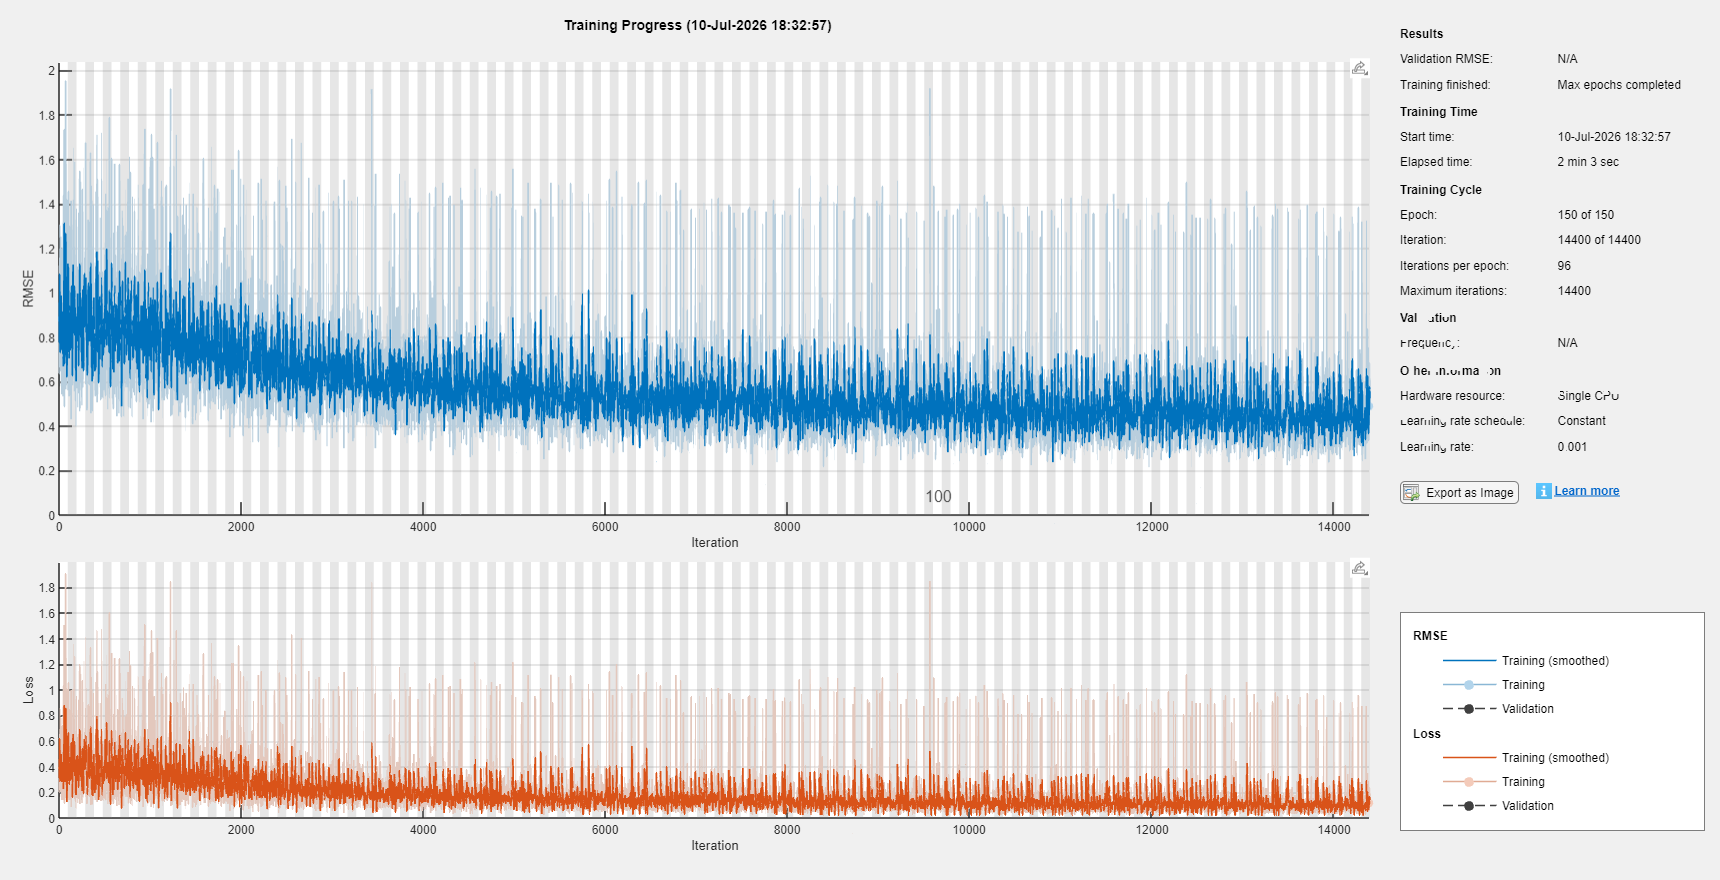


tic
net = trainNetwork(XTrain, YTrainN, layers, options);

trainingTime = toc;

fprintf('Training completed in %.2f seconds.\n', trainingTime);

Training completed in 126.42 seconds.



%% ================= PREDICTION ================================

YPredTrainN = predict(net, XTrain, "MiniBatchSize", miniBatchSize);
YPredTestN  = predict(net, XTest,  "MiniBatchSize", miniBatchSize);

% Denormalize
YPredTrain = YPredTrainN .* sigY + muY;
YPredTest  = YPredTestN  .* sigY + muY;

% Rainfall cannot be negative
YPredTrain(YPredTrain < 0) = 0;
YPredTest(YPredTest < 0)   = 0;


%% ================= PERFORMANCE METRICS =======================

trainMetrics = computeMetrics(YTrain, YPredTrain);
testMetrics  = computeMetrics(YTest, YPredTest);

fprintf('\n================ TRAINING PERFORMANCE ================\n');


================ TRAINING PERFORMANCE ================


fprintf('Correlation (r) = %.3f\n', trainMetrics.r);

Correlation (r) = 0.901


fprintf('RMSE            = %.3f mm/day\n', trainMetrics.RMSE);

RMSE            = 4.139 mm/day


fprintf('PBias           = %.3f %%\n', trainMetrics.PBias);

PBias           = 4.965 %


fprintf('KGE             = %.3f\n', trainMetrics.KGE);

KGE             = 0.799



fprintf('\n================ TESTING PERFORMANCE =================\n');


================ TESTING PERFORMANCE =================


fprintf('Correlation (r) = %.3f\n', testMetrics.r);

Correlation (r) = 0.911


fprintf('RMSE            = %.3f mm/day\n', testMetrics.RMSE);

RMSE            = 4.044 mm/day


fprintf('PBias           = %.3f %%\n', testMetrics.PBias);

PBias           = -0.194 %


fprintf('KGE             = %.3f\n', testMetrics.KGE);

KGE             = 0.828


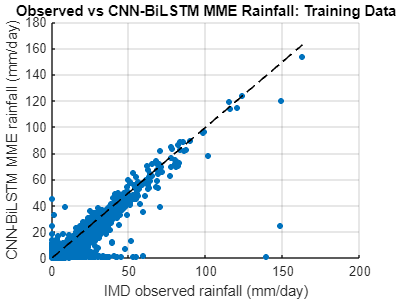



%% ================= PLOTS =====================================

% Training scatter plot
figure;
scatter(YTrain, YPredTrain, 20, 'filled'); hold on;
maxVal = max([YTrain; YPredTrain], [], 'omitnan');
plot([0 maxVal], [0 maxVal], 'k--', 'LineWidth', 1.2);
grid on;
xlabel('IMD observed rainfall (mm/day)');
ylabel('CNN-BiLSTM MME rainfall (mm/day)');
title('Observed vs CNN-BiLSTM MME Rainfall: Training Data');

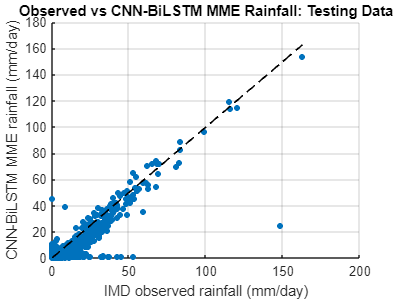


% Testing scatter plot
figure;
scatter(YTest, YPredTest, 20, 'filled'); hold on;
maxVal = max([YTest; YPredTest], [], 'omitnan');
plot([0 maxVal], [0 maxVal], 'k--', 'LineWidth', 1.2);
grid on;
xlabel('IMD observed rainfall (mm/day)');
ylabel('CNN-BiLSTM MME rainfall (mm/day)');
title('Observed vs CNN-BiLSTM MME Rainfall: Testing Data');


%% ================= LOCAL FUNCTION ============================


function metrics = computeMetrics(obs, sim)

    obs = obs(:);
    sim = sim(:);

    valid = ~isnan(obs) & ~isnan(sim);
    obs = obs(valid);
    sim = sim(valid);

    metrics.r = corr(obs, sim, 'Rows', 'complete');

    metrics.RMSE = sqrt(mean((sim - obs).^2, 'omitnan'));

    % PBias formulation:
    % Negative PBias = overestimation
    % Positive PBias = underestimation
    metrics.PBias = 100 * sum(obs - sim, 'omitnan') / sum(obs, 'omitnan');

    if numel(obs) < 3 || std(obs) == 0 || mean(obs) == 0
        metrics.KGE = NaN;
    else
        r = metrics.r;
        alpha = std(sim) / std(obs);
        beta  = mean(sim) / mean(obs);

        metrics.KGE = 1 - sqrt((r - 1)^2 + ...
                                (alpha - 1)^2 + ...
                                (beta - 1)^2);
    end

end